a)

figure(1);
stat = readtable("UCLA_EE_grad_2031.csv");
n = height(stat);
y = stat{:,3};
x = [ones(n,1) stat{:,1:2}]';

a = zeros(n,1);
noK = @(xtest, xi) (xtest' * xi);

for it = 1:1000
    for test = 1:n
        p = 0;
        for i = 1:n
            p = p + a(i) * y(i) * noK(x(:,test), x(:,i));
        end
        if y(test) * p <= 0
            a(test) = a(test) + 1;
        end
    end
end
w = x * (a .* y);
fprintf("no kernel w value:");

no kernel w value:

w

w =   -28.0000
    5.9282
    3.2447


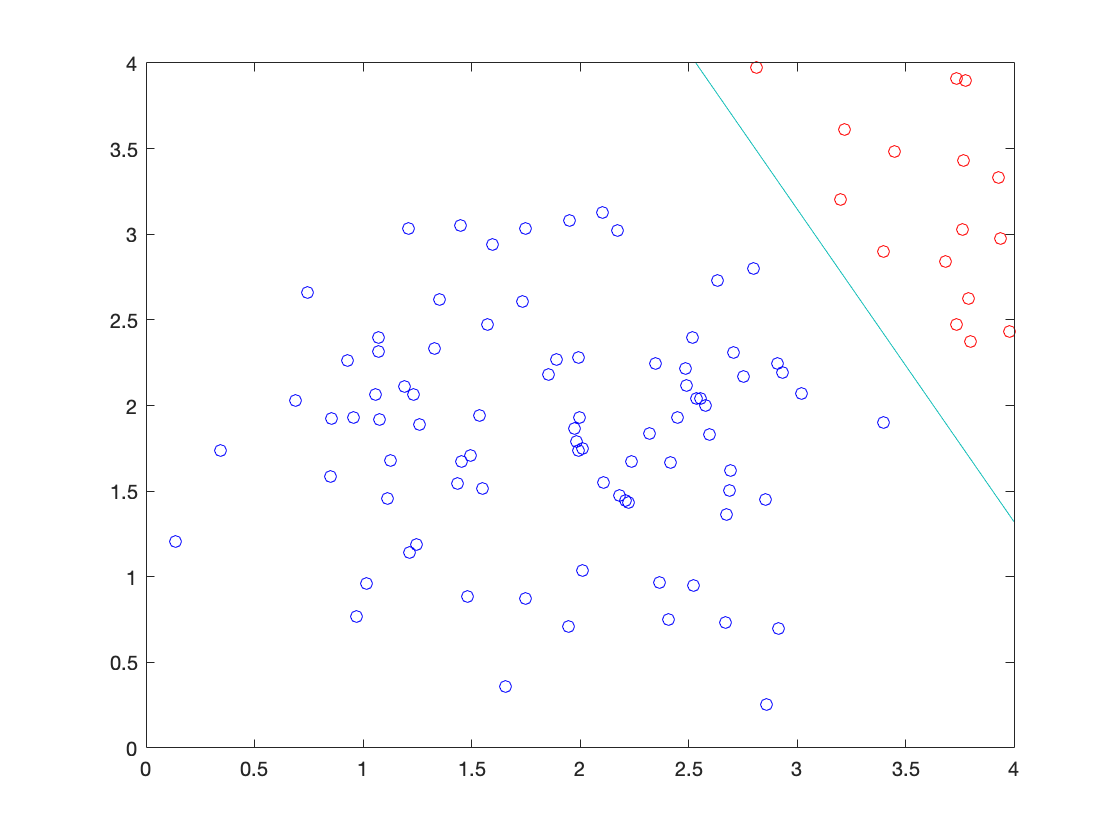


xrange = 0:0.1:4;
yrange = 0:0.1:4;
dim = length(xrange);
[x1, x2] = meshgrid(xrange, yrange);
Z = zeros(dim);
for r = 1:dim
    for c = 1:dim
        p = 0;
        for i = 1:n
            p = p + a(i) * y(i) * noK([1; x1(r,c); x2(r,c)], x(:,i));
        end
        Z(r,c) = p;
    end
end
contour(x1, x2, Z, 'LevelList', 0);
hold on;
GPA = x(2,:);
GRE = x(3,:);
scatter(GPA(y == -1), GRE(y == -1), 'blue');
scatter(GPA(y == 1), GRE(y == 1), 'red');

miss = 0;
for t = 1:n
    p = 0;
    for i = 1:n
        p = p + a(i) * y(i) * noK(x(:,t), x(:,i));
    end
    if (p * y(t) <= 0)
        miss = miss + 1;
    end
end
acc = 1 - miss/n;
fprintf("no kernel accuracy: %f\n", acc);

no kernel accuracy: 1.000000


b)

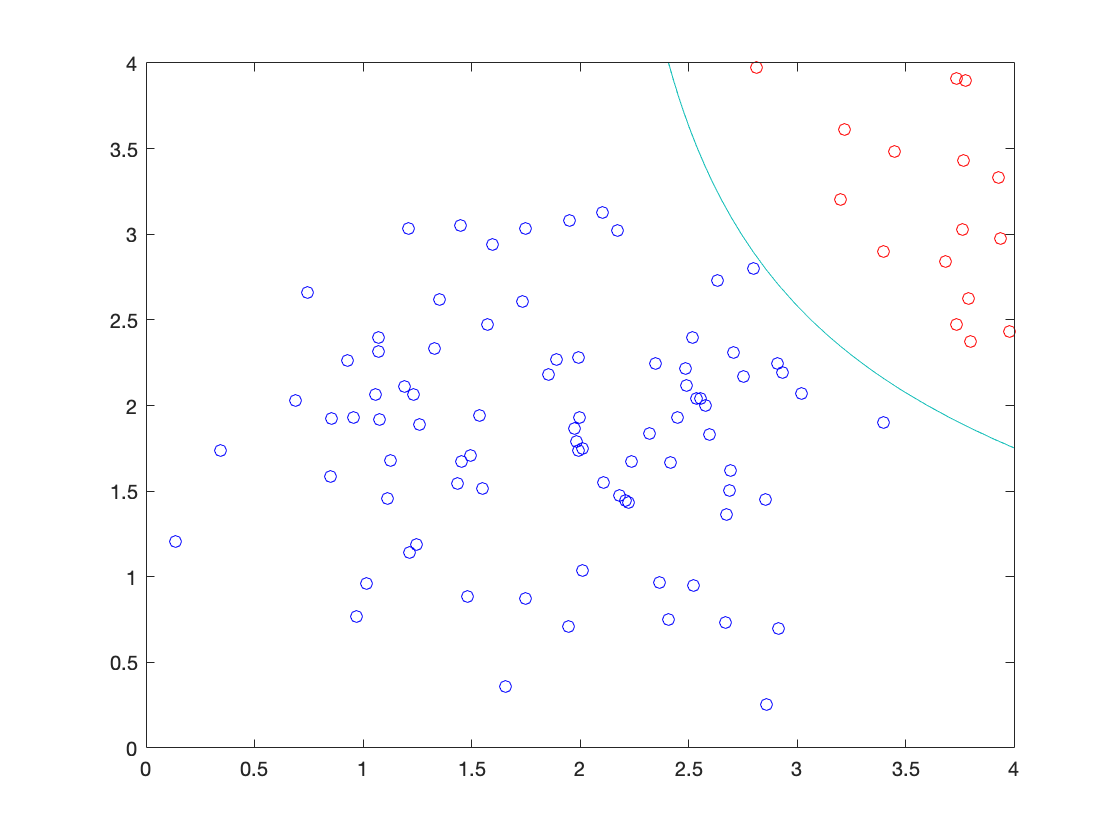

figure(2);

a = zeros(n,1);
poK = @(xtest, xi) (1 + xtest' * xi)^2;

for it = 1:1000
    for test = 1:n
        p = 0;
        for i = 1:n
            p = p + a(i) * y(i) * poK(x(:,test), x(:,i));
        end
        if y(test) * p <= 0
            a(test) = a(test) + 1;
        end
    end
end

xrange = 0:0.1:4;
yrange = 0:0.1:4;
dim = length(xrange);
[x1, x2] = meshgrid(xrange, yrange);
Z = zeros(dim);
for r = 1:dim
    for c = 1:dim
        p = 0;
        for i = 1:n
            p = p + a(i) * y(i) * poK([1; x1(r,c); x2(r,c)], x(:,i));
        end
        Z(r,c) = p;
    end
end
contour(x1, x2, Z, 'LevelList', 0);
hold on;
GPA = x(2,:);
GRE = x(3,:);
scatter(GPA(y == -1), GRE(y == -1), 'blue');
scatter(GPA(y == 1), GRE(y == 1), 'red');

miss = 0;
for t = 1:n
    p = 0;
    for i = 1:n
        p = p + a(i) * y(i) * poK(x(:,t), x(:,i));
    end
    if (p * y(t) <= 0)
        miss = miss + 1;    
    end
end
acc = 1 - miss/n;
fprintf("polynomial kernel accuracy: %f", acc);

polynomial kernel accuracy: 1.000000

(c)

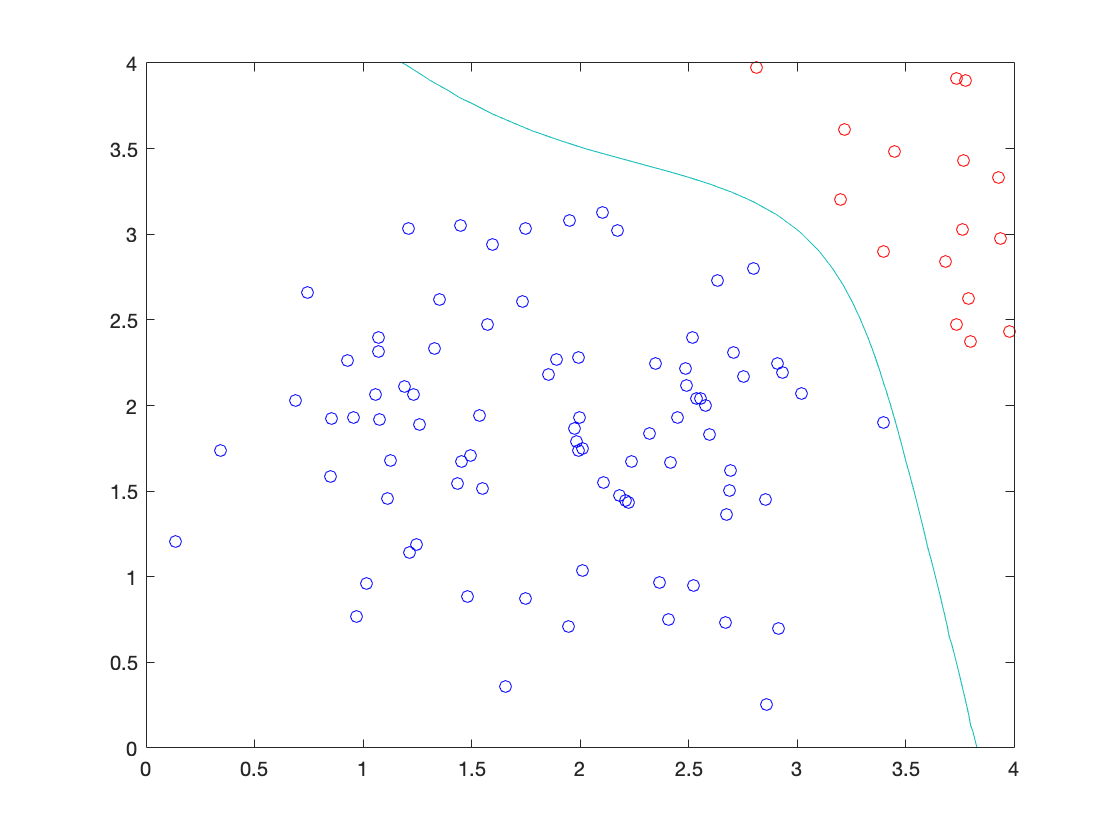

figure(3);

a = zeros(n,1);
gaK = @(xtest, xi) exp(-norm(xtest - xi)^2);

for it = 1:1000
    for test = 1:n
        p = 0;
        for i = 1:n
            p = p + a(i) * y(i) * gaK(x(:,test), x(:,i));
        end
        if y(test) * p <= 0
            a(test) = a(test) + 1;
        end
    end
end

xrange = 0:0.1:4;
yrange = 0:0.1:4;
dim = length(xrange);
[x1, x2] = meshgrid(xrange, yrange);
Z = zeros(dim);
for r = 1:dim
    for c = 1:dim
        p = 0;
        for i = 1:n
            p = p + a(i) * y(i) * gaK([1; x1(r,c); x2(r,c)], x(:,i));
        end
        Z(r,c) = p;
    end
end
contour(x1, x2, Z, 'LevelList', 0);
hold on;
GPA = x(2,:);
GRE = x(3,:);
scatter(GPA(y == -1), GRE(y == -1), 'blue');
scatter(GPA(y == 1), GRE(y == 1), 'red');

miss = 0;
for t = 1:n
    p = 0;
    for i = 1:n
        p = p + a(i) * y(i) * gaK(x(:,t), x(:,i));
    end
    if (p * y(t) <= 0)
        miss = miss + 1;
    end
end
acc = 1 - miss/n;
fprintf("gaussian kernel accuracy: %f", acc);

gaussian kernel accuracy: 1.000000

(d)

figure(4);
hold on;
stat = readtable("UCLA_EE_grad_2030.csv");
n = height(stat);
y = stat{:,3};
x = [ones(n,1) stat{:,1:2}]';
GPA = x(2,:);
GRE = x(3,:);
scatter(GPA(y == -1), GRE(y == -1), 'blue');
scatter(GPA(y == 1), GRE(y == 1), 'red');


a = zeros(n,1);
gaK = @(xtest, xi) exp(-norm(xtest - xi)^2);

for it = 1:1000
    for test = 1:n
        p = 0;
        for i = 1:n
            p = p + a(i) * y(i) * gaK(x(:,test), x(:,i));
        end
        if y(test) * p <= 0
            a(test) = a(test) + 1;
        end
    end
end

xrange = 0:0.1:4;
yrange = 0:0.1:4;
dim = length(xrange);
[x1, x2] = meshgrid(xrange, yrange);
Z = zeros(dim);
for r = 1:dim
    for c = 1:dim
        p = 0;
        for i = 1:n
            p = p + a(i) * y(i) * gaK([1; x1(r,c); x2(r,c)], x(:,i));
        end
        Z(r,c) = p;
    end
end
contour(x1, x2, Z, 'LevelList', 0, 'LineColor', 'red');

miss = 0;
for t = 1:n
    p = 0;
    for i = 1:n
        p = p + a(i) * y(i) * gaK(x(:,t), x(:,i));
    end
    if (p * y(t) <= 0)
        miss = miss + 1;
    end
end
acc = 1 - miss/n;
fprintf("2030 data now!");

2030 data now!

fprintf("gaussian sigma=1 kernel accuracy: %f", acc);

gaussian sigma=1 kernel accuracy: 0.980000


a = zeros(n,1);
gaK = @(xtest, xi) exp(-3 * norm(xtest - xi)^2);

for it = 1:1000
    for test = 1:n
        p = 0;
        for i = 1:n
            p = p + a(i) * y(i) * gaK(x(:,test), x(:,i));
        end
        if y(test) * p <= 0
            a(test) = a(test) + 1;
        end
    end
end

xrange = 0:0.1:4;
yrange = 0:0.1:4;
dim = length(xrange);
[x1, x2] = meshgrid(xrange, yrange);
Z = zeros(dim);
for r = 1:dim
    for c = 1:dim
        p = 0;
        for i = 1:n
            p = p + a(i) * y(i) * gaK([1; x1(r,c); x2(r,c)], x(:,i));
        end
        Z(r,c) = p;
    end
end
contour(x1, x2, Z, 'LevelList', 0, 'LineColor', 'blue');

miss = 0;
for t = 1:n
    p = 0;
    for i = 1:n
        p = p + a(i) * y(i) * gaK(x(:,t), x(:,i));
    end
    if (p * y(t) <= 0)
        miss = miss + 1;
    end
end
acc = 1 - miss/n;
fprintf("gaussian sigma=3 kernel accuracy: %f", acc);

gaussian sigma=3 kernel accuracy: 1.000000

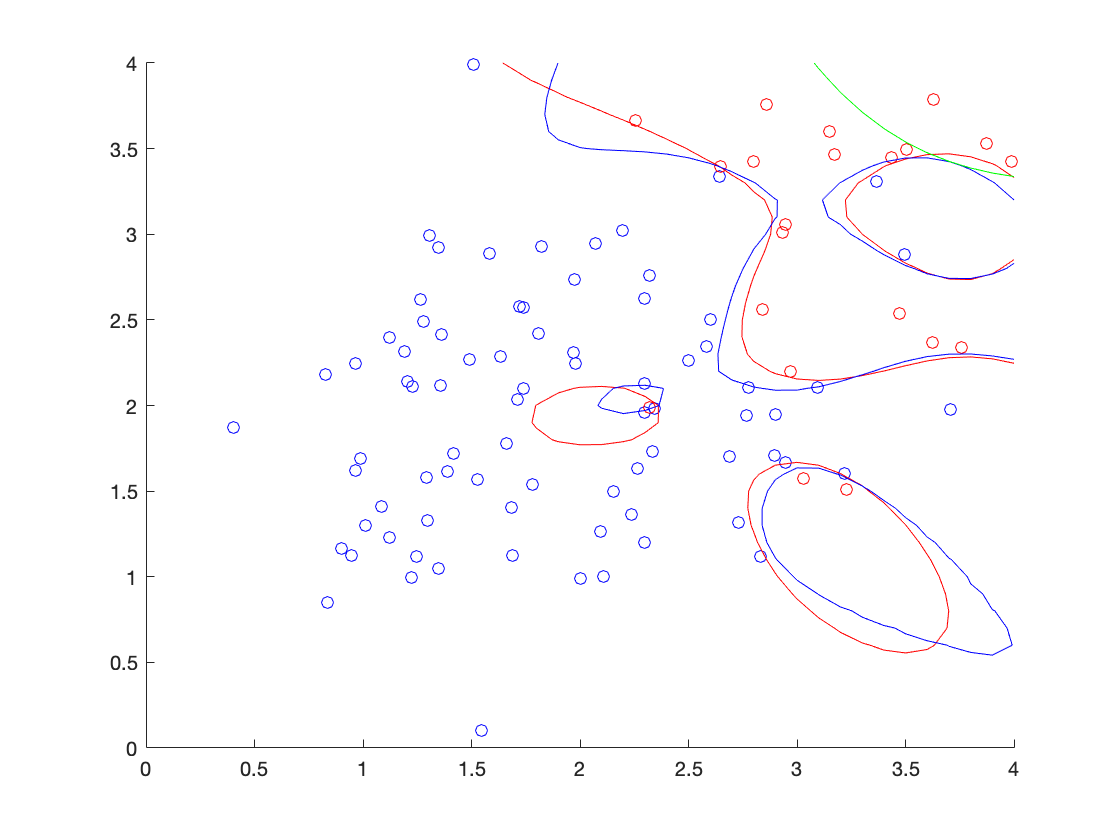


a = zeros(n,1);
poK = @(xtest, xi) (1 + xtest' * xi)^2;

for it = 1:1000
    for test = 1:n
        p = 0;
        for i = 1:n
            p = p + a(i) * y(i) * poK(x(:,test), x(:,i));
        end
        if y(test) * p <= 0
            a(test) = a(test) + 1;
        end
    end
end

xrange = 0:0.1:4;
yrange = 0:0.1:4;
dim = length(xrange);
[x1, x2] = meshgrid(xrange, yrange);
Z = zeros(dim);
for r = 1:dim
    for c = 1:dim
        p = 0;
        for i = 1:n
            p = p + a(i) * y(i) * poK([1; x1(r,c); x2(r,c)], x(:,i));
        end
        Z(r,c) = p;
    end
end
contour(x1, x2, Z, 'LevelList', 0, 'LineColor', 'green');


miss = 0;
for t = 1:n
    p = 0;
    for i = 1:n
        p = p + a(i) * y(i) * poK(x(:,t), x(:,i));
    end
    if (p * y(t) <= 0)
        miss = miss + 1;    
    end
end
acc = 1 - miss/n;
fprintf("polynomial degree=2 kernel accuracy: %f", acc);

polynomial degree=2 kernel accuracy: 0.820000

(d) The gaussian kernel with sigma equal to 1 had a 98 percent accuracy. The gaussian kernel with sigma equal to 3 had a 100 percent accuracy. It seems that if there is a higher sigma the accuracy is higher. The polynomial kernel was trash. It got 0.82 percent and only had 3 points in one of its classes. Only the gaussian kernel could get 100% because there were thingies inside the blue class that were part of the red class. (Was not linearly separable). 